# **RECEIPT CLASSIFIER**

## Datastore of images

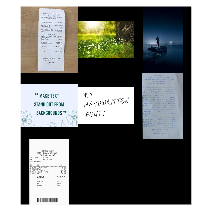

imgStore = datastore("UnfilteredImages");

% number of images
numberOfimgs = numel(imgStore.Files);

% create logical array of dimention 1 × no. of images
isReceipt = false(1, numberOfimgs);

montage(imgStore.Files);

## Image Checking

for n = 1 : numberOfimgs
    % traversing through the image datastore
    img = readimage(imgStore, n);

    isReceipt(n) = classifyImage (img);
end  

## Receipts found

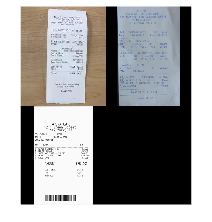

% Path of receipt found
receiptPath = imgStore.Files(isReceipt);

% number of reciepts found
numOfReceipts = nnz(isReceipt);

% displaying the receipts found
montage (receiptPath);

## Writing images to folder

for n = 1 : numOfReceipts
    path = string(receiptPath(n));
    img = imread(path);

    index = string(n);

    % Defining the image folder and image file name
    ImageFolder = 'ReceiptDetected';
    imgFileName = 'Receipt' + index + '.png';

    % Create the full file path
    fullFileName = fullfile(ImageFolder, imgFileName);

    % Save the image
    imwrite(img, fullFileName);
end

## **FUNCTIONS**

## Image Processing

function isImgReceipt = classifyImage (img)

### **    image conversion :** 

    % image convertion to grayscale 
    imgGray = im2gray(img);

### **    image Adjustment :**

    % adjusting contrast
    imgGray = imadjust(imgGray);

### **    image Segmentation :**    

- **Linear FIltering ** : smooth pixel intensity values

    % average matrix of 3*3 size
    filter = fspecial ("average", 3); 
    imgSmooth = imfilter(imgGray, filter, "replicate");

-  **Morphological Operations**

    % create struture element disk of radius 8
    struElement = strel("disk", 8);

    % closing (dilate) for background and noises enhancement
    % Text is black/dark on receipt, thus closing will remove it
    % and bring out the background and noises
    imgBG = imclose(imgSmooth, struElement);

    % Removing high intensity background from image
    imgClean = imgBG - imgSmooth;

    % Binarize the image (convert to black & White (0 & 1), or binary image)
    % using ~ as intensity values has been shifted during substraction
    imgBinary = ~imbinarize(imgClean);

    % If receipt then image will have text, converting text to strips
    % as opening enhances dark parts, using it to convert to stipes
    struElement = strel("rectangle", [3 25]);
    imgStripes = imopen(imgBinary, struElement);

### **    image Classification :**

    % receipt will have a row sum without text high value (1+)
    % and with text less value (dark text)
    rowSum = sum (imgStripes, 2);

    minIndices = islocalmin(rowSum,"MinProminence",70,"ProminenceWindow",25);

    % number of non zero indices or minima
    indices = nnz(minIndices);

    % if 9 or more minima then its a receipt
    isImgReceipt = indices >= 7;
end